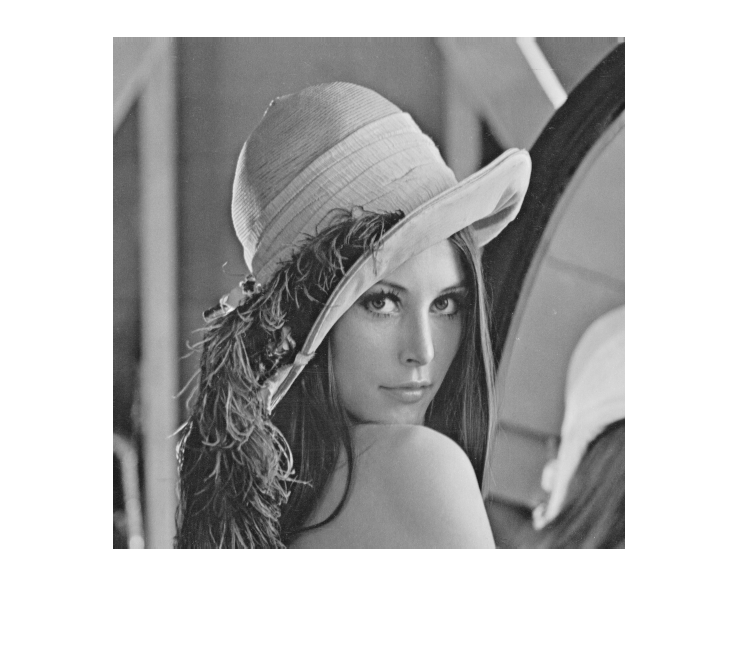

lena=imread("Lenna.png");
lena=rgb2gray(lena);
imshow(lena);

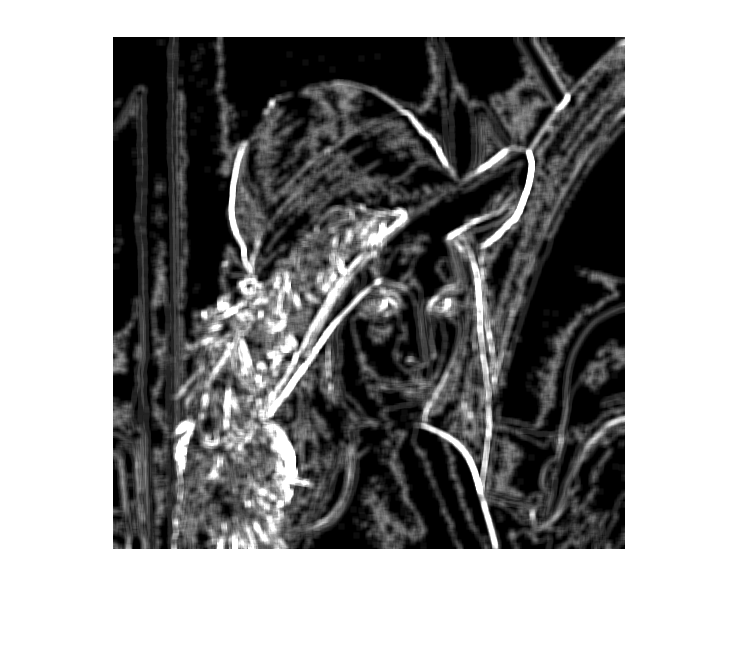

[m,n]=size(lena);
img_c=zeros(m,n);
img_e=zeros(m,n);
img_h=zeros(m,n);
img_corr=zeros(m,n);
for i=1:m
    for j=1:n
        value=ceil(lena(i,j)/32);
        if (value==0)
            value=1;
        end
        lena(i,j)=value;
    end
end
for i=1:m
    for j=1:n
        patch=get_patch(7,i,j,lena);

        gray_matrix=GLCM(patch,8);
        img_c(i,j)=get_contrast(gray_matrix);
        img_e(i,j)=get_Energy(gray_matrix);
        img_h(i,j)=get_Homo(gray_matrix);
        img_corr(i,j)=get_corr(gray_matrix);
    end
end
imshow(img_c);

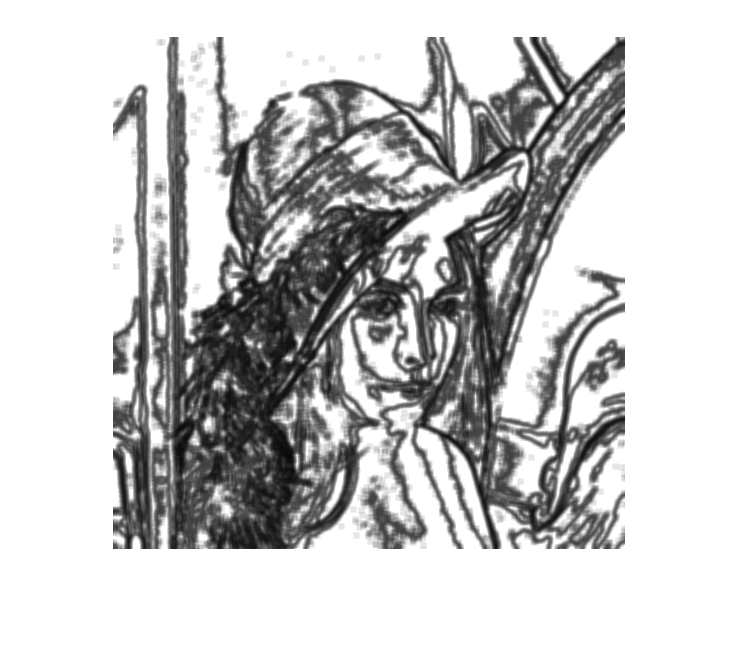

imshow(img_e);

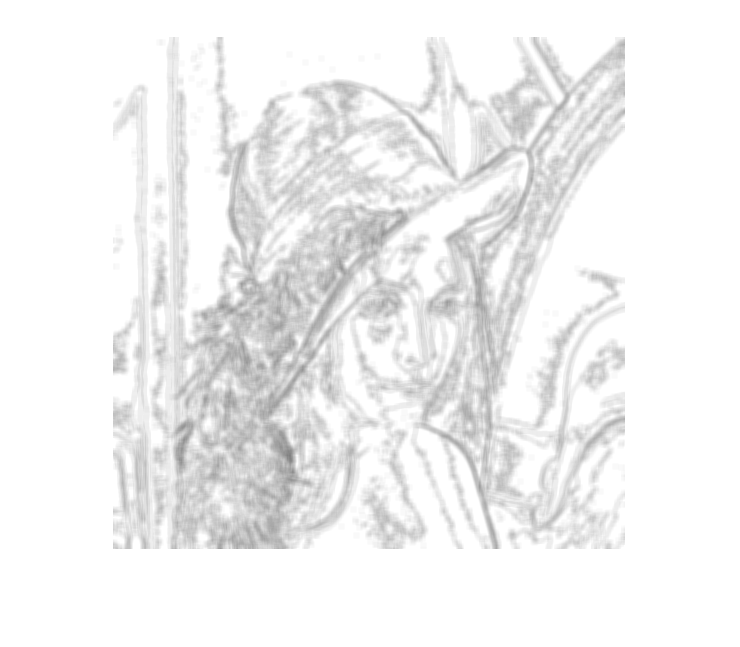

imshow(img_h);

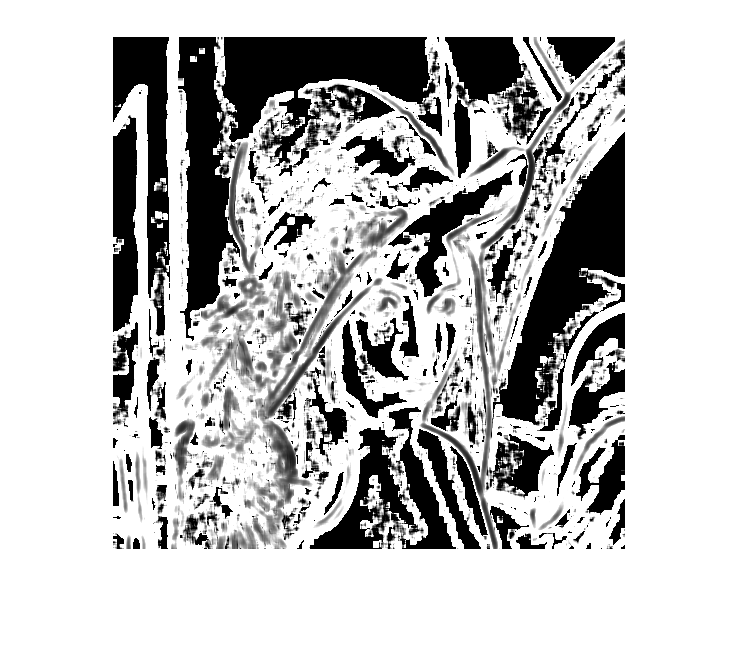

imshow(img_corr);